clear all
close all
clc

run("BASIC.m")
C=poly([0.6 0.7]);

Question_mark='Q14-MA nonadaptive';
[uc,t,Status,tfinal,Noise]=Datagen_Stochastic(2,0.1,500,0.01,C);

Status = '-Cololerd NOISE-'

Titlework=[Question_mark,Status]

Titlework = 'Q14-MA nonadaptive-Cololerd NOISE-'

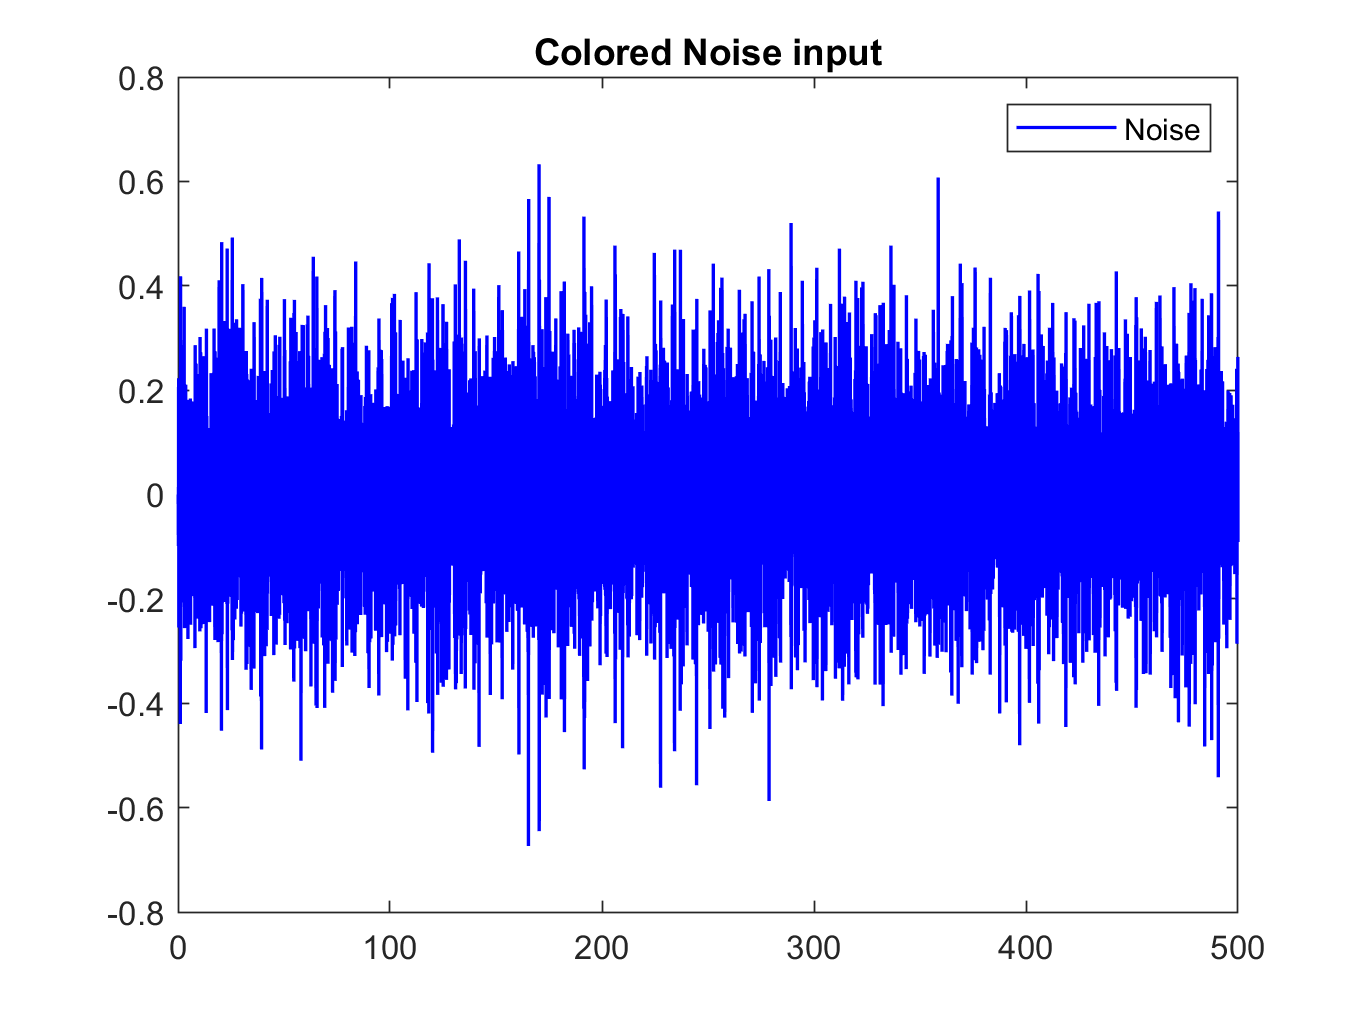

plot(t,Noise,'b','LineWidth',1)
title('Colored Noise input')
legend('Noise')
print(gcf,[Titlework , num2str(plot_counter) ' Colored Noise input.png'],'-dpng','-r400');

plot_counter=plot_counter+1;


d=2;

B_plus=[1]          ;
Ac=conv(C,B_plus)   ;
D0=[1 zeros(1,d-1)] ;
D0=[1 0] ;

Ac=conv(Ac,D0)      ;


ACLS_y=[0 0];
ACLS_u=[0 0];



[R , S ] = Diophantine(A , B , Ac) 

R =     1.0000   -0.8278


S =     0.4978   -0.1376


for ii=1:length(Noise)
    varer(ii)=var(Noise(1:ii));
end

uc=uc*0;
y=[0 0];
u=zeros(1,2);
for i=3:numel(t)
    
    y(i)= -A(2:3)*[y(i-1:-1:i-2)]'+ B*[uc(i-1:-1:i-2)]+Noise(i);
    u(i)=(-R(2)*u(i-1)-S*[y(i:-1:i-1)]');

    var_u (i)=var(u)        ;mean_u(i)=mean(u)      ;ACLS_u(i)=u(i)^2+ACLS_u(i-1)       ;
    var_y(i)=var(y)   ;mean_y(i)=mean(y);ACLS_y(i)=y(i)^2+ACLS_y(i-1) ;
end

## Output and control signal plotting

General Input v.s. Output

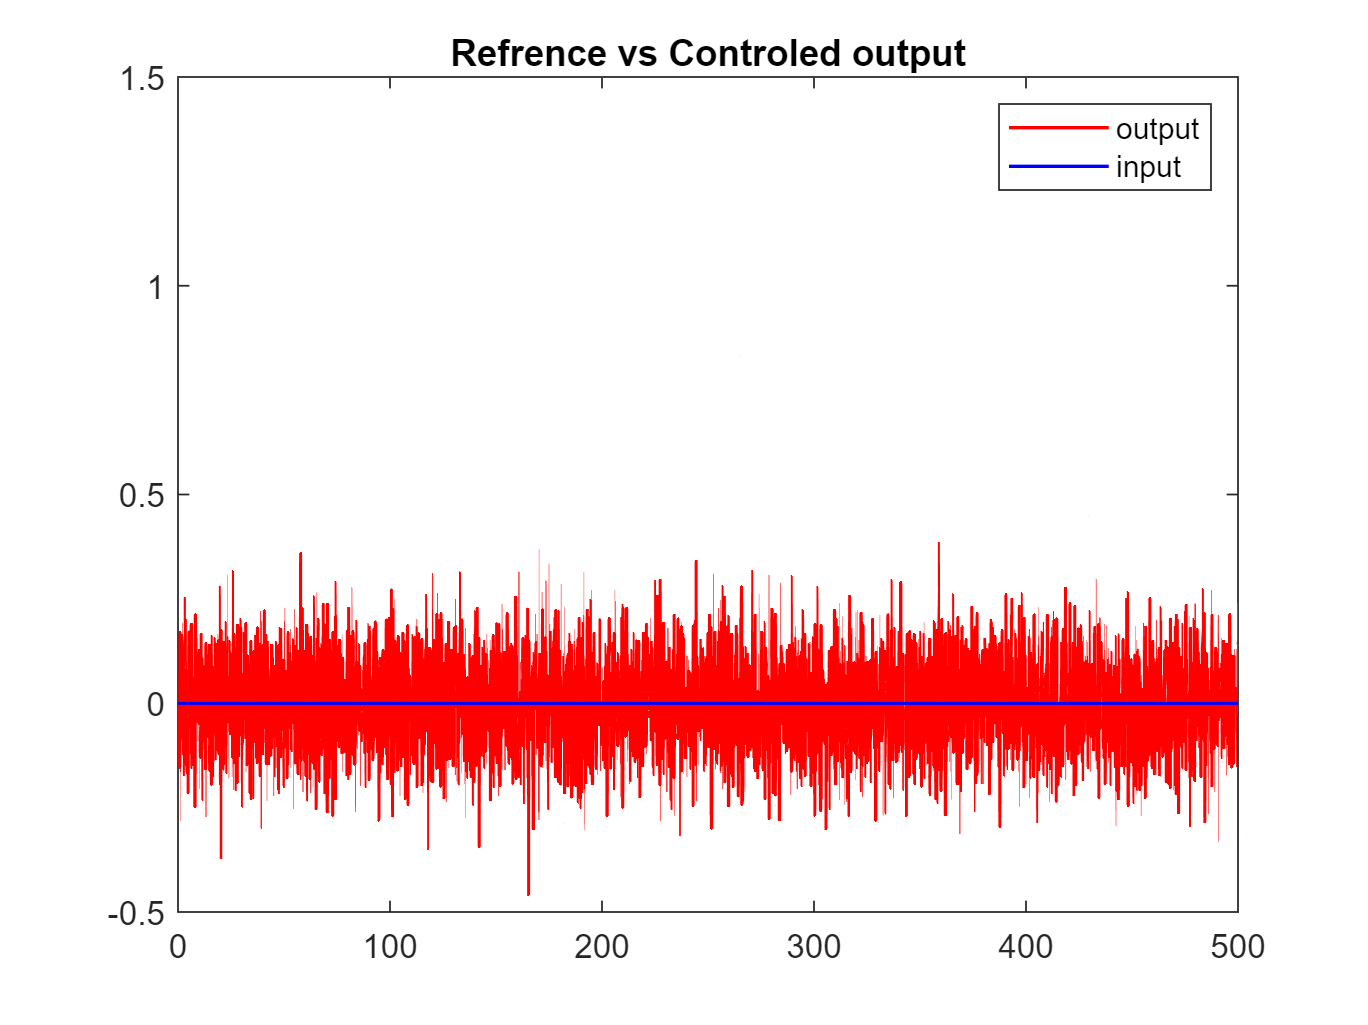

plot(t,y,'r-',t,uc,'b','LineWidth',1)
title('Refrence vs Controled output')
legend('output','input')
xlim('auto')
ylim([-0.5 1.5])
print(gcf,[Titlework , num2str(plot_counter) ' Refrence vs Controled output.png'],'-dpng','-r400');

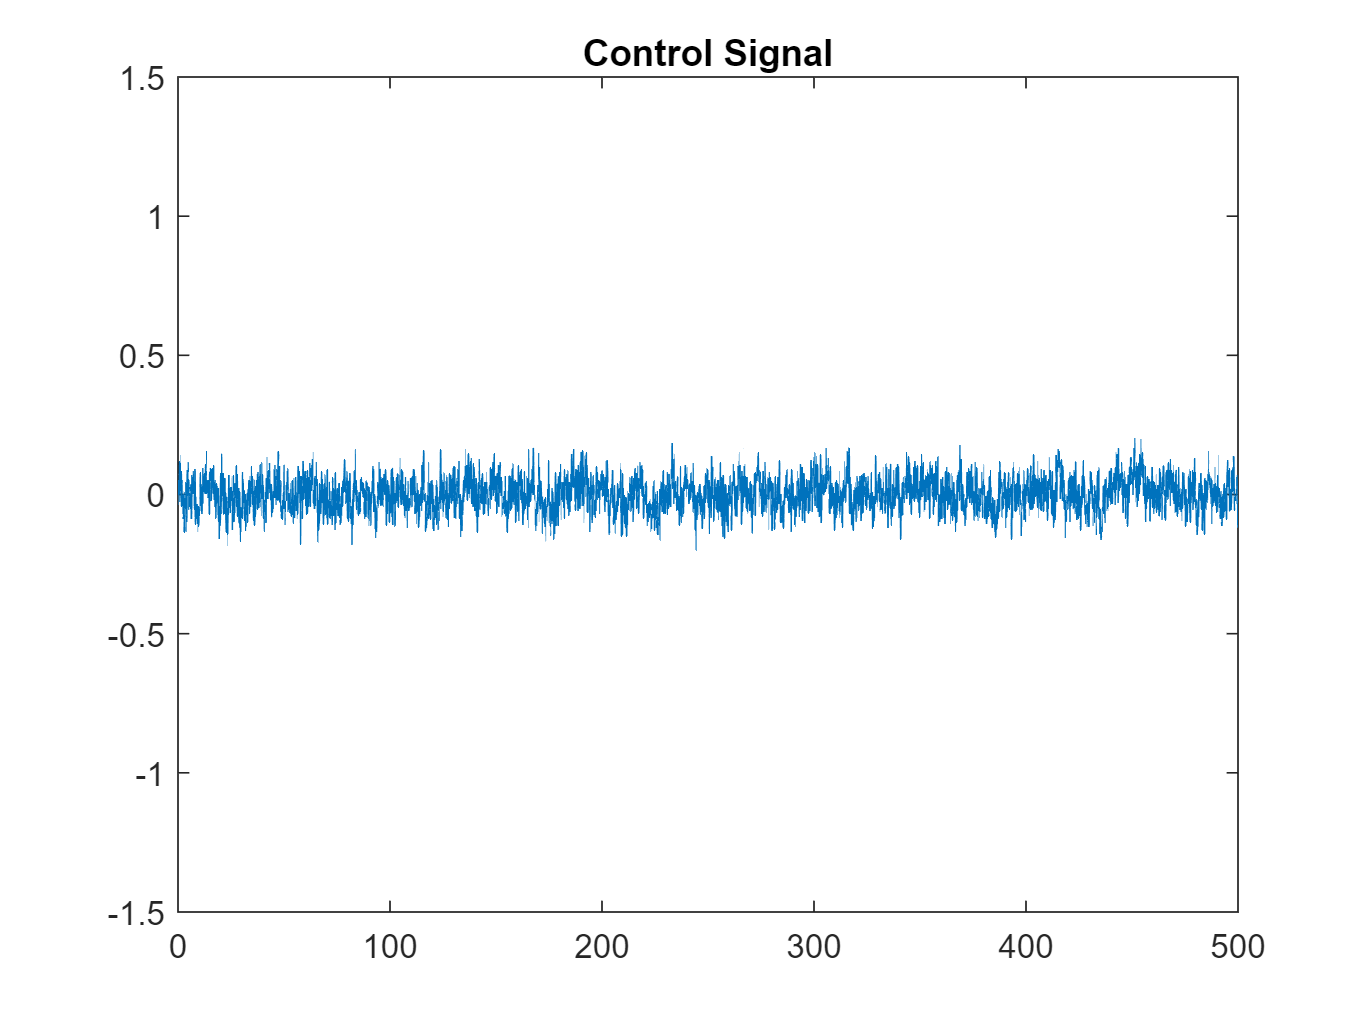

plot_counter=plot_counter+1;

plot(t,u)
title('Control Signal')
xlim('auto')
ylim([-1.5 1.5])
print(gcf,[Titlework , num2str(plot_counter) ' Control Signal.png'],'-dpng','-r400');

plot_counter=plot_counter+1;

## Variance plotting

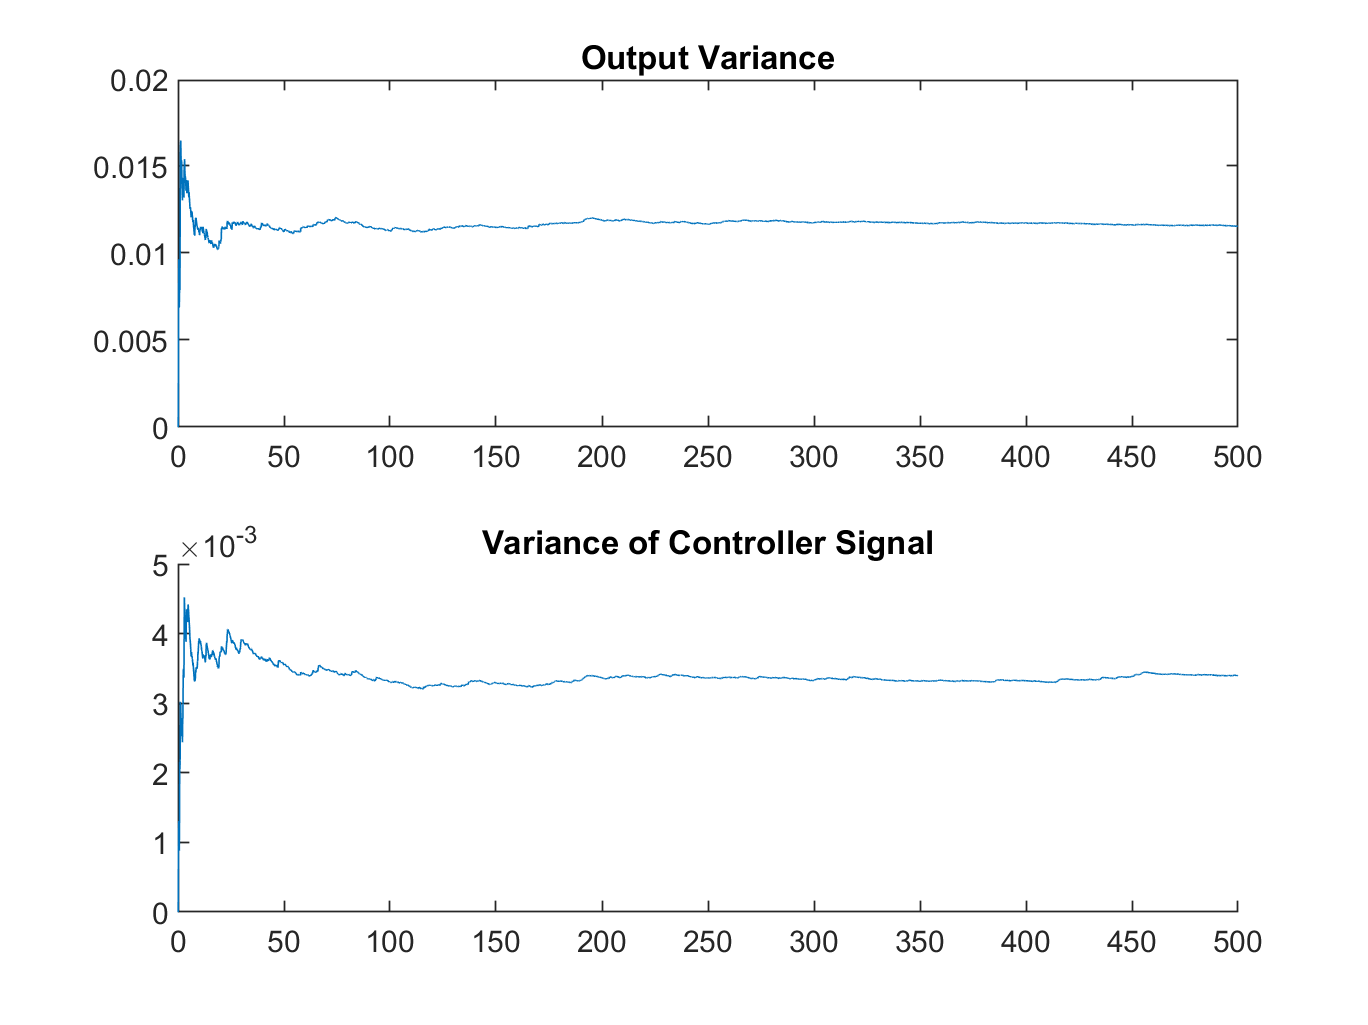

figure
subplot(211)
plot(t,var_y)
hold on
title('Output Variance')

subplot(212)
hold on
title('Variance of Controller Signal')
plot(t,var_u)
print(gcf,[Titlework , num2str(plot_counter) ' Variance.png'],'-dpng','-r400');

plot_counter=plot_counter+1;

## Mean plotting

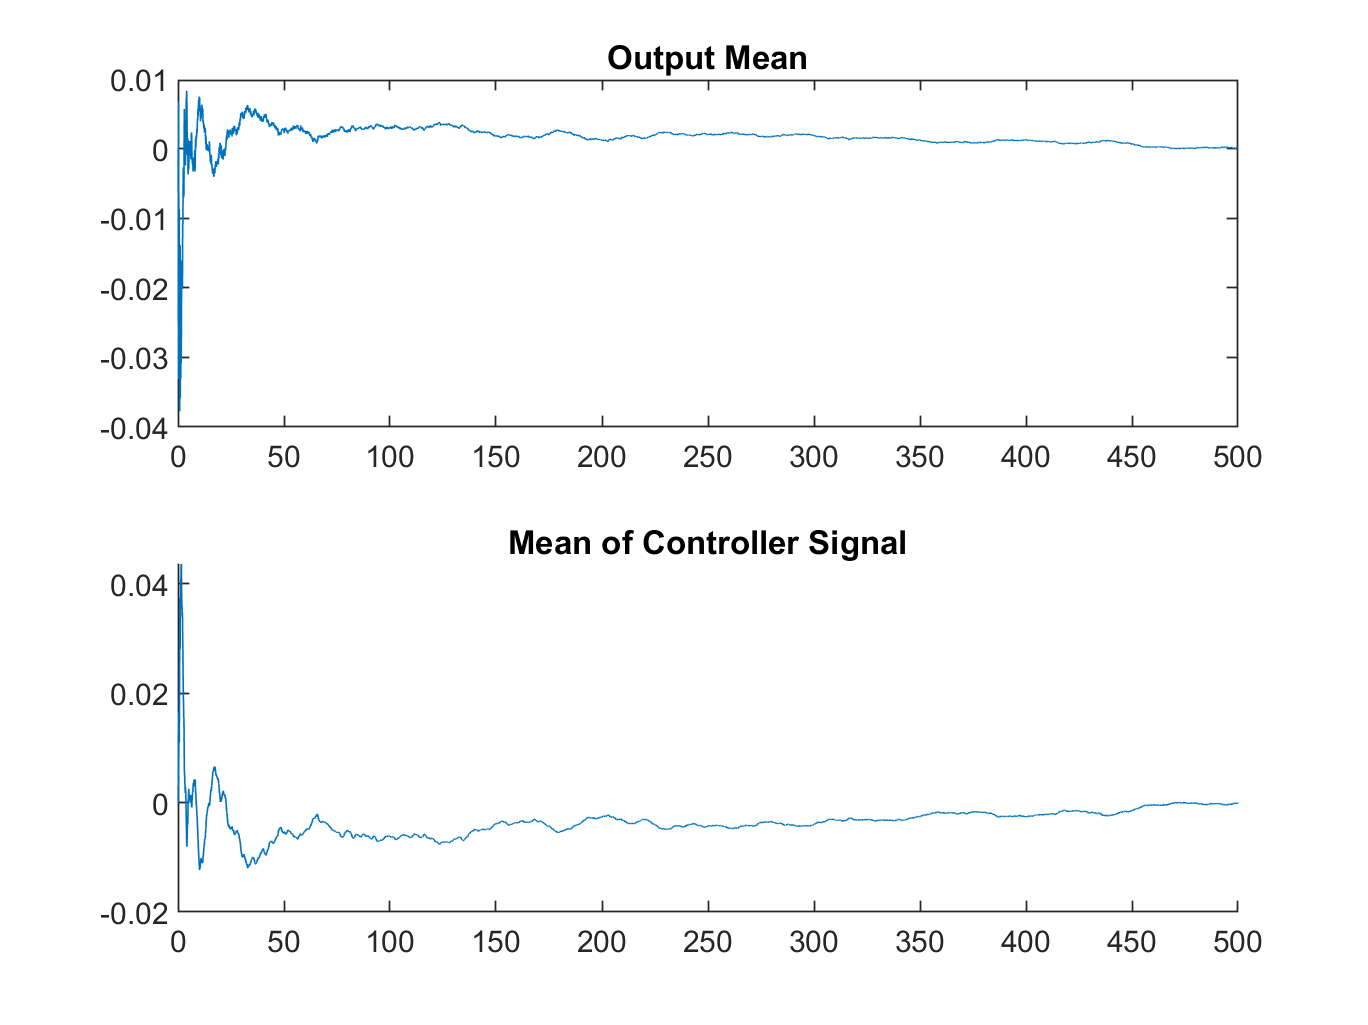

figure
subplot(211)
plot(t,mean_y)
hold on
title('Output Mean')

subplot(212)
hold on
plot(t,mean_u)
title('Mean of Controller Signal')
print(gcf,[Titlework , num2str(plot_counter) ' mean.png'],'-dpng','-r400');

plot_counter=plot_counter+1;

## Accumulated loss plotting

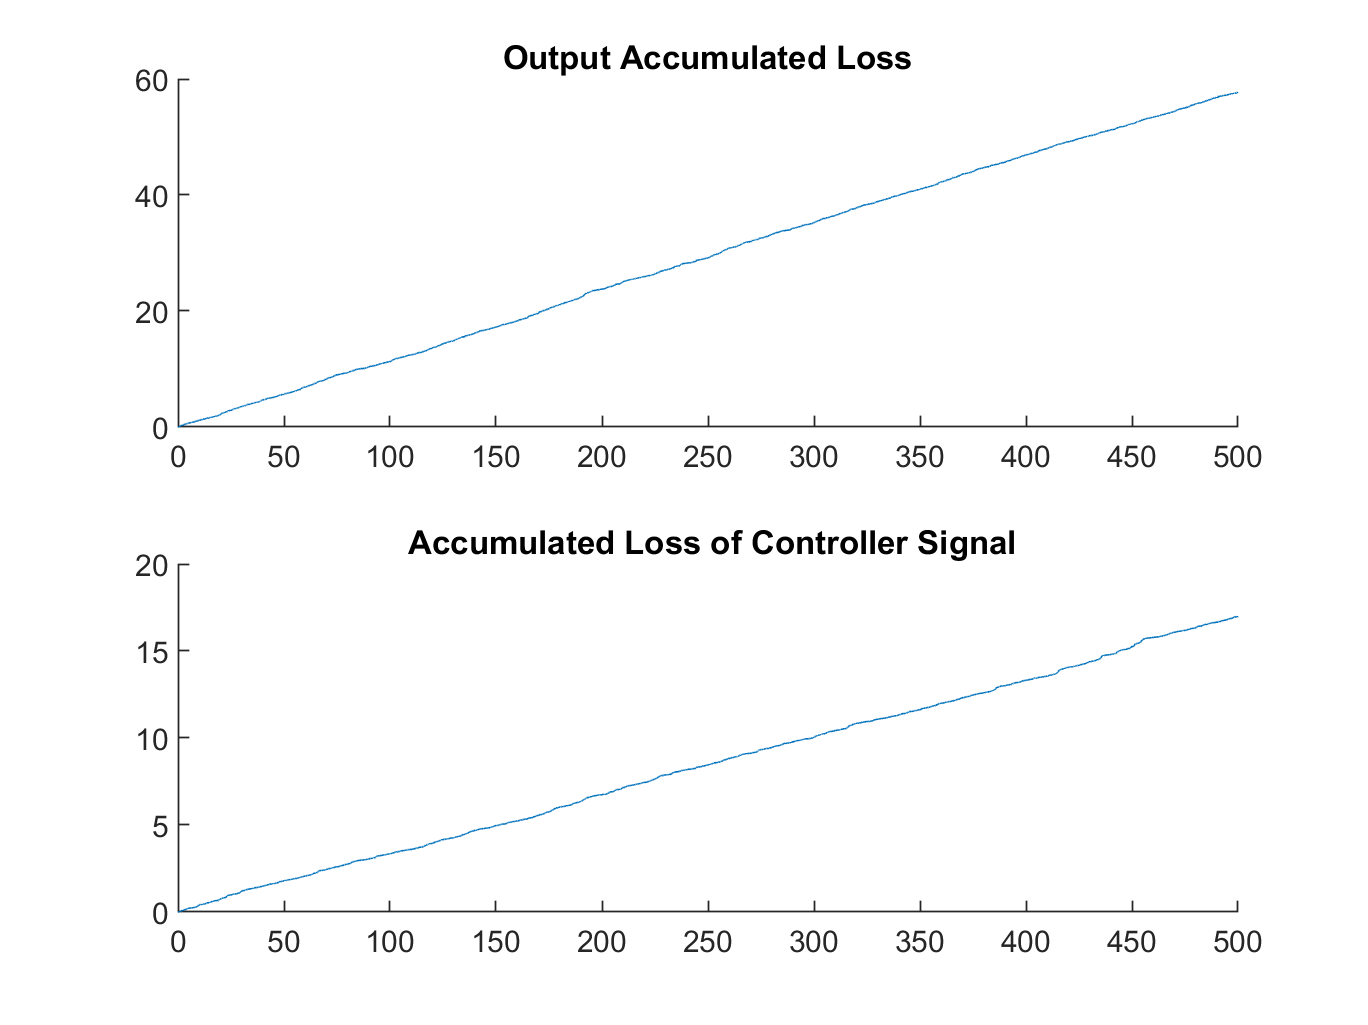

figure
subplot(211)
hold on
plot(t,ACLS_y)
title('Output Accumulated Loss')

subplot(212)
hold on
title(' Accumulated Loss of Controller Signal')
plot(t,ACLS_u)
print(gcf,[Titlework , num2str(plot_counter) ' Accumulated Loss.png'],'-dpng','-r400');

plot_counter=plot_counter+1;